RE = 6378.1; % km 
RM = 384400; % km
mu = 398600.4415; % km^3/s^2
e = 1; % eccentricity of a parabola

alt_rp = 200; %km
rp = alt_rp + RE; % km
energy = 0;
p = 2*rp;
rc = rp;
vc = sqrt(mu/rc);
v_esc = sqrt(2)*vc;
h = sqrt(2*mu*rp);
v_esc/vc;

## Part b)

r1 = 3*RE

r1 = 1.9134e+04

[v1,th1,th1_deg,t1] = vtht(r1,mu,rp,p)

v1 = 6.4547

th1 = 1.8885

th1_deg = 108.2056

t1 = 2.7016e+03

r2 = 20*RE

r2 = 127562

[v2,th2,th2_deg,t2] = vtht(r2,mu,rp,p)

v2 = 2.4999

th2 = 2.6834

th2_deg = 153.7489

t2 = 3.6546e+04

r3 = 100*RE

r3 = 637810

[v3,th3,th3_deg,t3] = vtht(r3,mu,rp,p)

v3 = 1.1180

th3 = 2.9381

th3_deg = 168.3425

t3 = 3.8617e+05

r4 = 200*RE

r4 = 1275620

[v4,th4,th4_deg,t4] = vtht(r4,mu,rp,p)

v4 = 0.7905

th4 = 2.9978

th4_deg = 171.7640

t4 = 1.0840e+06

r5 = RM

r5 = 384400

[v5,th5,th5_deg,t5] = vtht(r5,mu,rp,p)

v5 = 1.4401

th5 = 2.8792

th5_deg = 164.9666

t5 = 1.8246e+05

r6 = 3000*RE

r6 = 19134300

[v6,th6,th6_deg,t6] = vtht(r6,mu,rp,p)

v6 = 0.2041

th6 = 3.1045

th6_deg = 177.8752

t6 = 6.2527e+07

## Part c)

rp = 200 + RE;
ra = RM;
a = (rp + ra)/2;
e = ra / a - 1;
p = a*(1-e^2);
b = a*sqrt(1-e^2);
th_moon = pi;
th_moon_deg = 180;
E_moon = pi; E_moon_deg = 180;
vm_ellipse = sqrt(mu*(2/RM - 1/a));
v5/vm_ellipse;
t_e_moon = sqrt(a^3/mu)*(E_moon-e*sind(E_moon))/3600/24;

### Part d)

th_d = -120;
Cep_rth = [cosd(th_d), sind(th_d); -sind(th_d), cosd(th_d)];
Crth_ep = [cosd(th_d), -sind(th_d); sind(th_d), cosd(th_d)];

rmag_d = p/(1+cosd(th_d))

rmag_d = 2.5870e+04

r_d = rmag_d.*[cosd(th_d) sind(th_d)]

r_d = 	1.0e+04 *

   -1.2935   -2.2404


vmag_d = sqrt(2*mu/rmag_d)

vmag_d = 5.5512

gamma = -rad2deg(acos(h/vmag_d/rmag_d))

gamma = -59.7178

v_d = vmag_d.*[sind(gamma),cosd(gamma)]

v_d =    -4.7938    2.7993


v_d = Crth_ep * v_d'

v_d =     4.8211
    2.7519


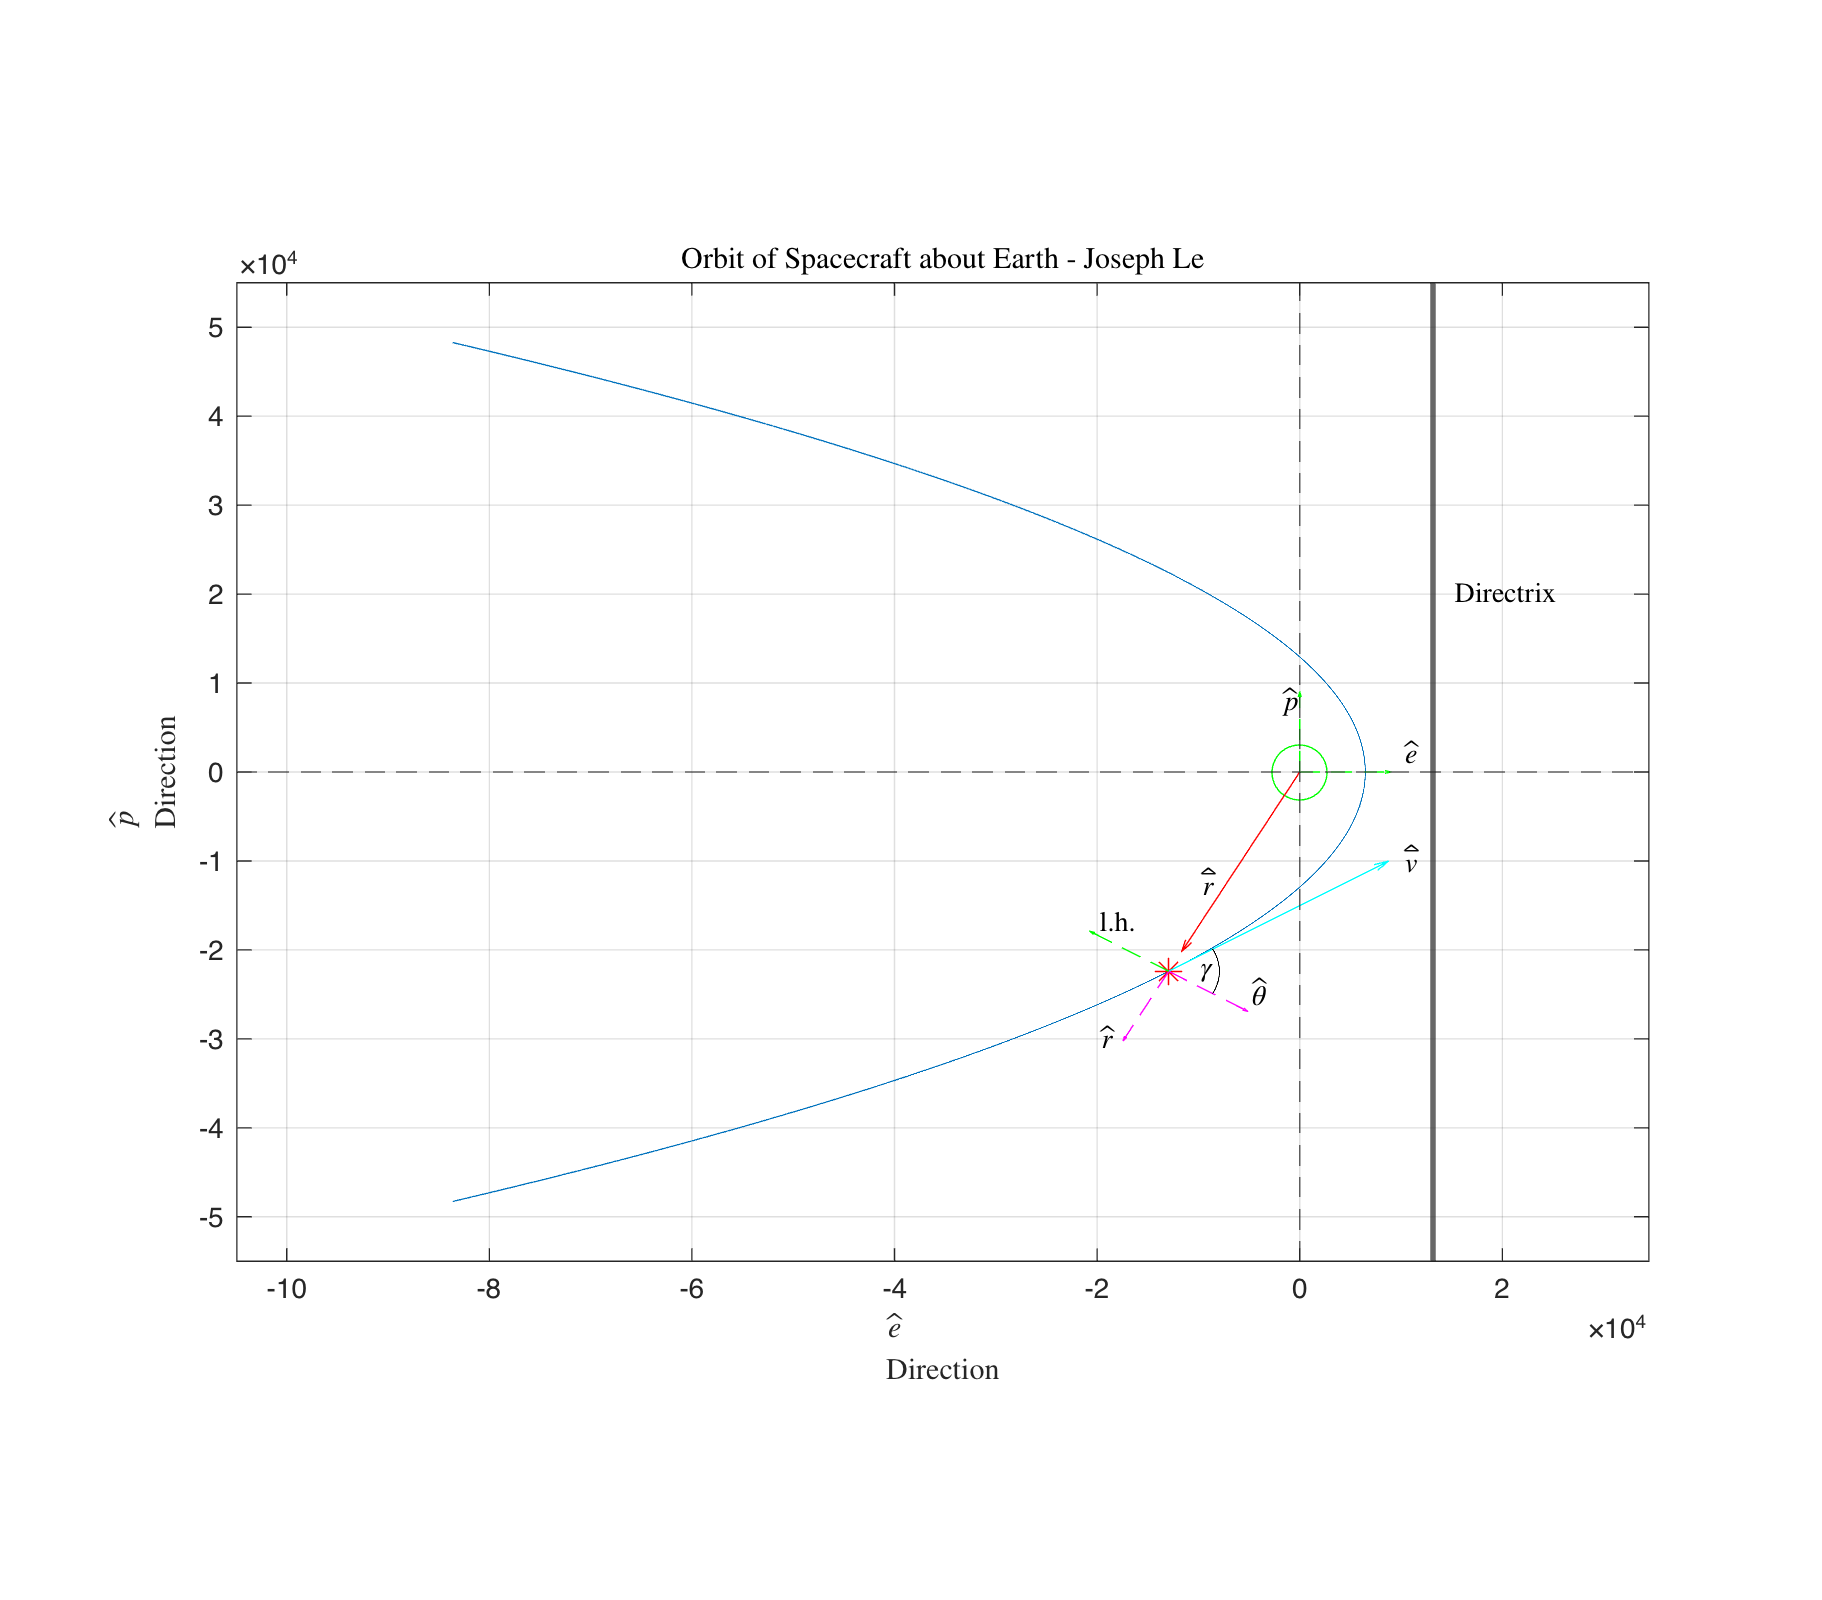

th_deg = linspace(-150,150,2^14);
th = deg2rad(th_deg);
rmag = p./(1+cos(th));
rx = rmag.*cos(th);
ry = rmag.*sin(th);
plot(rx,ry)
grid on, axis equal
hold on
plot(0,0,'go',"MarkerSize",20)

plot(r_d(1),r_d(2),'r*',"MarkerSize",10)
quiver(r_d(1),r_d(2),'r')
quiver(r_d(1),r_d(2),5e3*v_d(1),5e3*v_d(2),'c')

% plot unit vectors
quiver(0,1e4,'g--'), quiver(1e4,0,'g--')
xline(2*rp,"LineWidth",2)
xline(0,'--')
yline(0,'--')
quiver(r_d(1),r_d(2),cosd(th_d)*1e4,sind(th_d)*1e4,'m--')
quiver(r_d(1),r_d(2),-sind(th_d)*1e4,cosd(th_d)*1e4,'m--')
quiver(r_d(1),r_d(2),sind(th_d)*1e4,-cosd(th_d)*1e4,'g--')
ylim(1e4.*[-5.5 5.5])
set(gcf,'position',[0,0,1080,1080])
text(1e4,.2e4,'$$\hat{e}$$','Interpreter','Latex')
text(-.2e4,.8e4,'$$\hat{p}$$','Interpreter','Latex')
text(-2e4,-3e4,'$$\hat{r}$$','Interpreter','Latex')
text(-.5e4,-2.5e4,'$$\hat{\theta}$$','Interpreter','Latex')
text(-1e4,-1.26e4,'$$\hat{\bar{r}}$$','Interpreter','Latex')
text(1e4,-1e4,'$$\hat{\bar{v}}$$','Interpreter','Latex')
text(-2e4,-1.7e4,'l.h.','Interpreter','Latex')
text(1.5e4,2e4,'Directrix','Interpreter','Latex')
plotcircle(r_d(1),r_d(2),deg2rad(th_d+90),deg2rad(90+gamma),.5e4)
text(-1e4,-2.2e4,'$$\gamma$$','Interpreter','Latex')
xlabel('$$\hat{e}$$ Direction','Interpreter','Latex'),ylabel('$$\hat{p}$$ Direction','Interpreter','Latex')
title('Orbit of Spacecraft about Earth - Joseph Le','Interpreter','Latex')

Function 1: Problem 2b calculations

function [v,th,th_deg,t] = vtht(r,mu,rp,p)
v = sqrt(2*mu/r);
th = acos(2*rp/r -1);
th_deg = rad2deg(th);
D = tan(th/2);
t = sqrt(p^3/(4*mu))*(D+1/3 * D^3); % Barker's Equation
end

Function 2: plot circle

function plotcircle(x0,y0,theta0,thetaf,r)
th = linspace(theta0,thetaf,2^10);
x = r*cos(th)+x0;
y = r*sin(th)+y0;
plot(x,y,'k')
end